# Taratura manuale dell'anello di velocità

Determinare $C(s)$ in modo che soddisfi una frequenza di taglio desirata

In quest'esempio il controllore è un PI


$$C(s)=PI(s)=\frac{K_p\cdot s+K_i}{s}=K_p\left(1+\frac{1}{T_i s}\right)=K_p \frac{T_i s +1}{T_i s}$$


il processo è la funzione di trasferimento, in questo caso coppia - velocità lato motore

clear all;close all;clc;
load ../identificazione_e_validazione/model_joint3.mat
Ts=1e-3;
s=tf('s');
sys_vel_motore=tf(modello_continuo);

Con funzione di trasferimento

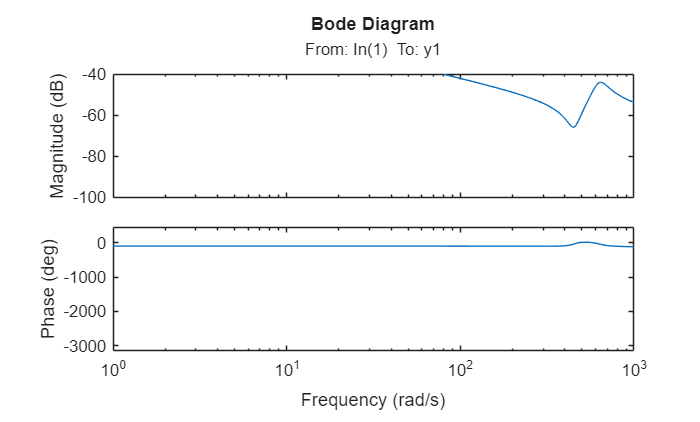

figure
bode(sys_vel_motore)
xlim([1 1000])

Vorrei un $\omega_c$ prossima all'antirisonanza (che è attorno a 450 rad/s)

wc=200;

L'azione integrale mi sfasa, la metto almeno una decade prima.

wi=wc/20; % pulsazione azione integrale
Ti=1/wi;

Il mio controllore sarà


$$C(s)=K_p \left(1+1/(Ti\cdot s)\right)=K_p C_o(s)$$


con $C_o(s)=$

s=tf('s');
Co=1+1/(Ti*s);

Calcolo $K_p$ in modo che $C(s)*P(s)=K_p \left(C_o(s)*P(s)\right)$ abbia modulo 1 in $\omega_c$. 

$|K_p \left(C_o(j\omega_c)*P(j\omega_c)\right)|=1 $ quindi $K_p=1/| \left(C_o(j\omega_c)*P(j\omega_c)\right)|$

Kp=1/abs(freqresp(Co*sys_vel_motore,wc));
C=Kp*Co


C =
 
  27.63 s + 276.3
  ---------------
       0.1 s
 
Continuous-time transfer function.


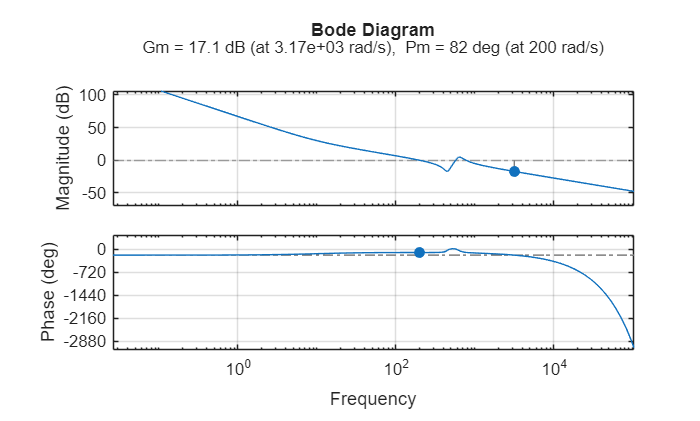

figure
margin(C*sys_vel_motore)
grid on

Il diagramma di bode taglia più volte, meglio aggiungere un filtro per abbassare il picco.

#### Filtro Notch

Un filtro notch è un'elimina banda. La zona da eliminare è 

damp(sys_vel_motore)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -6.33e-12                 1.00e+00       6.33e-12         1.58e+11    
 -6.21e+01 + 6.28e+02i     9.84e-02       6.31e+02         1.61e-02    
 -6.21e+01 - 6.28e+02i     9.84e-02       6.31e+02         1.61e-02    


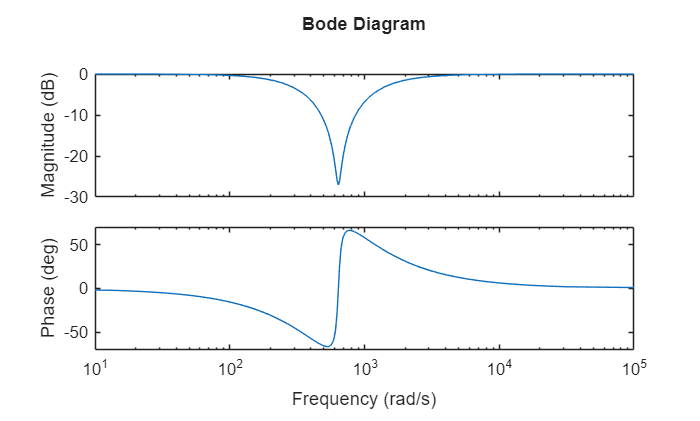

wn=640; % prima era alla frequenza dell'antirisonanza ma noi l'abbiamo messo a quella della risonanza
xci_z=0.04; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.9;
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
figure
bode(notch)

Per il PI, il "nuovo" sistema da controllare è

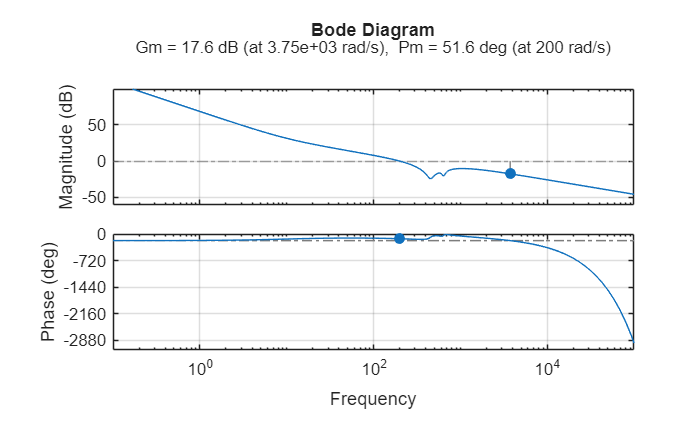

P=sys_vel_motore*notch;
Kp=1/abs(freqresp(Co*P,wc));
C=Kp*Co;
figure
margin(C*P)
grid on

Potrei voler aggiungere altri poli (ad esempio un passa basso)

Display Valori pid

Kp

Kp = 325.4262

Ki = Kp/Ti

Ki = 3.2543e+03

# Taratura manuale dell'anello di posizione

**ATTENZIONE: eseguire solo dopo aver eseguito tutto il resto **

Calcolo della Funzione di Trasferimento a ciclo chiuso dell'anello di velocità

L_vel = C * P;                  % Anello aperto di velocità
F_vel = feedback(L_vel, 1);     % Anello chiuso di velocità

Definizione dell'impianto per l'anello di posizione

% P_posizione = F_anello_vel * (1/s)
s = tf('s');
P_pos = F_vel * (1/s);           % L'integrale della velocità dà la posizione


Scelta della frequenza di taglio per la posizione (wc_pos)

% REGOLA: L'anello esterno deve essere più lento di quello interno
% circa tra 1/5 e 1/3 di wc della velocità.
wc_pos = 140;                     % Frequenza di taglio desiderata (rad/s)

% Calcolo del controllore Proporzionale (Kp)
% Calcoliamo la magnitudo dell'impianto di posizione alla frequenza wc_pos
[mag_pos, phase_pos, wout] = bode(P_pos, wc_pos);

% Il controllore è solo Kp, e Kp = 1 / |P_pos(wc_pos)|
Kp_pos = 1 / mag_pos;
C_pos = Kp_pos;                  % Il controllore di posizione è puramente proporzionale

Verifica dei risultati

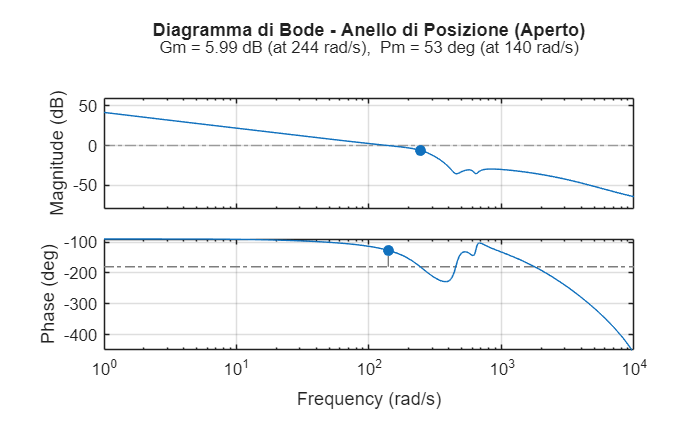

L_pos = C_pos * P_pos;           % Funzione di trasferimento ad anello aperto (posizione)

% Plottiamo il diagramma di Bode per verificare la stabilità (Margine di Fase)
figure;
margin(L_pos);
title('Diagramma di Bode - Anello di Posizione (Aperto)');
grid on;

% Mostriamo il valore del Kp calcolato nella command window
disp(['Il valore del guadagno proporzionale Kp per la posizione è: ', num2str(Kp_pos)]);

Il valore del guadagno proporzionale Kp per la posizione è: 123.1322
